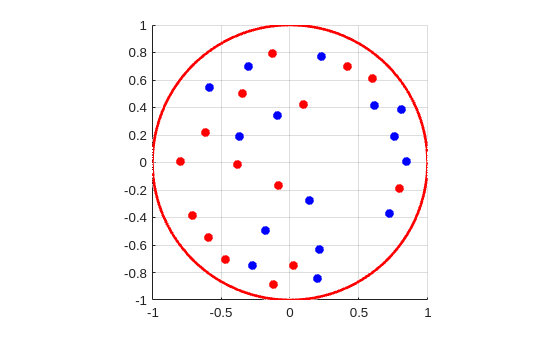

N=30;
p=15; % these are the purple tracks (kinesin)
a_k=4; b_k=13; a_d=1; b_d=5;

alpha_kin_over_alpha_dyn=1;
xi=b_d/b_k*alpha_kin_over_alpha_dyn;
psi=a_k*b_d/(a_d*b_k); % xi and psi are the relative important of kinesin and dynein
delta=1e-5; % finite difference for gradient computation
alpha=0; % alpha=0 for closed, alpha=oo for open
lambda=0.05;

state='closed';
min_distance=0.2;
min_distance_boundary=0.2;
r=sqrt(rand(N,1));
theta=2*pi*rand(N,1);
x=[r.*cos(theta),r.*sin(theta)];
x=repel(contain_1(repel(x,min_distance),min_distance_boundary),min_distance);

x_0=x;
fun=@(x,x_start) 1;
% quarters
%fun=@(x,x_start) (x(:,1).*x_start(:,1)>0)+(x(:,2).*x_start(:,2)>0)-1.5;

% % thirds
% fun=@(x,x_start)...
% (atan2(x(:,2),x(:,1))<-pi/3).*(atan2(x_start(:,2),x_start(:,1))<-pi/3)+...
% (atan2(x(:,2),x(:,1))<pi/3).*(atan2(x(:,2),x(:,1))>-pi/3).*...
% (atan2(x_start(:,2),x_start(:,1))<pi/3).*(atan2(x_start(:,2),x_start(:,1))>-pi/3)+...
% (atan2(x(:,2),x(:,1))>pi/3).*(atan2(x_start(:,2),x_start(:,1))>pi/3)-0.5;
% 
% % fifths
% fun=@(x,x_start)...
% (atan2(x(:,2),x(:,1))<-3*pi/5).*(atan2(x_start(:,2),x_start(:,1))<-3*pi/5)+...
% (atan2(x(:,2),x(:,1))<-pi/5).*(atan2(x(:,2),x(:,1))>-3*pi/5).*...
% (atan2(x_start(:,2),x_start(:,1))<-pi/5).*(atan2(x_start(:,2),x_start(:,1))>-3*pi/5)+...
% (atan2(x(:,2),x(:,1))<pi/5).*(atan2(x(:,2),x(:,1))>-pi/5).*...
% (atan2(x_start(:,2),x_start(:,1))<pi/5).*(atan2(x_start(:,2),x_start(:,1))>-pi/5)+...
% (atan2(x(:,2),x(:,1))<3*pi/5).*(atan2(x(:,2),x(:,1))>pi/5).*...
% (atan2(x_start(:,2),x_start(:,1))<3*pi/5).*(atan2(x_start(:,2),x_start(:,1))>pi/5)+...
% (atan2(x(:,2),x(:,1))>3*pi/5).*(atan2(x_start(:,2),x_start(:,1))>3*pi/5)-0.5;

N_steps=5000;
gamma=1e-2;

clf
scatter(x(1:p,1),x(1:p,2),'MarkerEdgeColor','blue','MarkerFaceColor','blue')
hold on
scatter(x(p+1:end,1),x(p+1:end,2),'MarkerEdgeColor','red','MarkerFaceColor','red')
viscircles([0,0],1);
axis equal
axis tight
grid on
hold off

Lagrangian_start=Lagrangian(N,p,x,xi,psi,state);
fprintf('The initial value of the Lagrangian is %f',Lagrangian_start)

The initial value of the Lagrangian is -28.604453

%CellArea=CircleBV(x(:,1),x(:,2),0)
%x=x_old;
x_old=x;
%x=x+randn(N,2)*0.05;



gamma=0.1;
for i=1:100
% x=repel(contain_1(x+gamma*Lagrangian_Gradient_alpha(N,p,x,xi,psi,delta,alpha),...
%     min_distance_boundary),min_distance);
x=contain_1(segregate(repel(x+gamma*Lagrangian_Gradient(N,p,x,xi,psi,delta,state),...
    min_distance),x_old,x_0,fun),min_distance_boundary);
x_old=x;
end

Lagrangian_end=Lagrangian(N,p,x,xi,psi,state);
fprintf('The final value of the Lagrangian is %f',Lagrangian_end)

The final value of the Lagrangian is 169.511068

if Lagrangian_end <=Lagrangian_start
    warning('Gradient descent failed')
end

pseudo_velocities=Velocities(N,p,x,xi,psi,state);
velocities=pseudo_velocities*a_d/(b_d^2*log(lambda)^2);
mean(pseudo_velocities(1:p))-a_k/b_k

ans = 2.7093

mean(pseudo_velocities(p+1:end))+a_d/b_d

ans = 8.4837

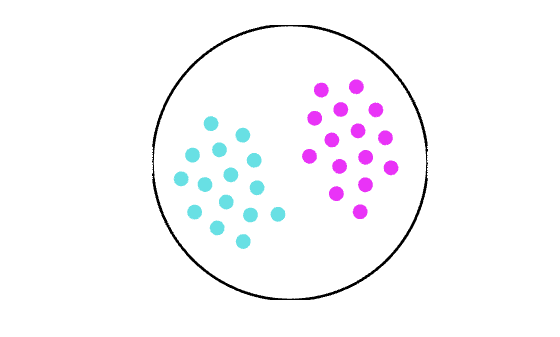

clf
% scatter(x(1:p,1),x(1:p,2),'MarkerEdgeColor','blue','MarkerFaceColor','blue')
% hold on
% scatter(x(p+1:end,1),x(p+1:end,2),'MarkerEdgeColor','red','MarkerFaceColor','red')

% kinesin
for i=1:p
    rectangle('Position',[x(i,1)-lambda,x(i,2)-lambda,2*lambda,2*lambda],...
        'Curvature',[1 1],'EdgeColor',[0.914 0.2 0.969],'FaceColor',[0.914 0.2 0.969])
end

% dynein
hold on
for i=p+1:N
    rectangle('Position',[x(i,1)-lambda,x(i,2)-lambda,2*lambda,2*lambda],...
        'Curvature',[1 1],'EdgeColor',0.9*[0.455 0.976 0.992],'FaceColor',0.9*[0.455 0.976 0.992])
end


viscircles([0,0],1,'Color',[0 0 0]);
axis equal
axis tight
set(gca,'visible','off')
hold off


% filename=['Segregated_TR_Five.mat'];
% save(filename,'x','x_0','N','p','xi','psi','alpha','delta',...
%     'min_distance_boundary','min_distance','N_steps',...
%     'gamma');

% centres=[0 0; 0.5 0];
% rho_i=[1 0.1];
% a_vec=[-4]';
% b_vec=[13];

centres=[0, 0; x];
rho_i=[1,lambda*ones(1,N)];
a_vec=[-a_k*ones(1,p),a_d*ones(1,N-p)]';
b_vec=[b_k*ones(1,p),b_d*ones(1,N-p)];

flux=0;

if flux~=0 && strcmp(state,'growing')~=1
    fprintf('The flux can only be declared nonzero if the axon is growing.\nSetting flux to 0')
    flux=0;
end

max_mesh_spacing=0.02;

model=createpde(1);

N_circles=numel(rho_i);
ns='C'+string((1:N_circles));
ns=char(ns');
ns=ns';
% Create a character array (column vector)

sf=['(C' num2str(1) '-C' num2str(2) ')'];
for i=3:N_circles
sf=['(' sf '-C' num2str(i) ')'];
end
% sf tells matlab what combination of shapes (union, intersection etc) to
% take

C=zeros(4,N_circles); % describe the shapes (same order as in ns)
C(1,:)=ones(1,N_circles);
C(2,:)=centres(:,1)';
C(3,:)=centres(:,2)';
C(4,:)=rho_i;
gm = C;
% A create a matrix whose columns contain the basic shapes making up the domain

g = decsg(gm,sf,ns); %
geometryFromEdges(model,g); % add geometry to model
mesh=generateMesh(model,"Hmax",max_mesh_spacing,'GeometricOrder',"linear");

%pdemesh(mesh)
[p,e,t] = meshToPet(model.Mesh);
N_pts=size(p,2);

[K,~,F1,~,~,~,~]=assempde(model,-1,0,1); % Ks discrete Laplacian on the vertices
%K=K*diag(1./F);

% find what centre boundary points are closest to
boundary_num=(abs(sqrt((p(1,e(1,:))'-centres(:,1)').^2+(p(2,e(1,:))'-centres(:,2)').^2)+...
    -rho_i)<1e-6)*(1:N_circles)';

% sparse(ind_1,ind_2, values, size_1, size_2)
dirichelt_mat=sparse(e(1,:),e(1,:),1,N_pts,N_pts);
E_mat=sparse(e(1,boundary_num~=1),boundary_num(boundary_num~=1)-1,1,...
    N_pts,numel(rho_i)-1); % E

TR=triangulation(t(1:3,:)',p');
tr=t(1:3,cell2mat(edgeAttachments(TR,e(1:2,:)')));
third_ngb=tr(ismember(tr,e(1:2,:))==0)';

drag_matrix_bdry=zeros(size(centres,1)-1,N_pts);

for bdry=2:size(centres,1)
index_array=boundary_num==bdry;
difference_matrix=sparse(e(1,index_array), third_ngb(index_array),...
    1,N_pts,N_pts)+sparse(e(1,index_array),e(1,index_array),-1,...
    N_pts,N_pts);

weight_vector=sparse(1,e(1,index_array),...
    vecnorm(p(:,e(1,index_array))-p(:,e(2,index_array)),2,1)./...
((vecnorm(p(:,third_ngb(index_array))-centres(bdry,:)',2,1)-rho_i(bdry))),...
1,N_pts);
drag_matrix_bdry(bdry-1,:)=weight_vector*difference_matrix;
end

drag_matrix_bdry=sparse(drag_matrix_bdry);
B_mat=sparse(diag(b_vec));
M_1=B_mat\drag_matrix_bdry;
M_2=B_mat\a_vec;

if strcmp(state,'closed')==1 || strcmp(state,'growing')==1
tr=t(1:3,:);
mat1=repmat(1:size(t,2),3,1);
[~,AE] = area(mesh);
area_vec=AE*sparse(mat1(:),tr(:),1,size(t,2),N_pts)/3;

tic
lambda_1=10^4*mean(abs(K),'all');
lambda_2=10^2*mean(abs(K),'all');
% u=(lambda_1*(E_mat*M_1-dirichelt_mat)-K+F1*(F1'*K)/norm(F1)^2+lambda_2*...
%     sparse(1,1,1,N_pts,1)*area_vec)...
%     \(lambda_1*E_mat*M_2);
options = optimoptions('lsqlin','Display','none');
u=lsqlin(lambda_1*(E_mat*M_1-dirichelt_mat)-K+F1*(F1'*K)/norm(F1)^2,...
    lambda_1*E_mat*M_2,[],[],area_vec,flux,[],[],[],options);
omega=M_1*u-M_2;
toc
end

Elapsed time is 11.367117 seconds.



% u=cat(1,K,E_mat*M_1-dirichelt_mat)\...
%    cat(1,sparse(N_pts,1),E_mat*M_2); 

if strcmp(state,'open')
lambda=10^4*mean(abs(K),'all');
u=(lambda*(E_mat*M_1-dirichelt_mat)-K)\(lambda*E_mat*M_2);
omega=M_1*u-M_2;
end

%mean(omega(1:25))
%mean(omega(26:30))
%sum_kinesin=sum_kinesin+sum(omega(1:15));
%sum_dynein=sum_dynein+sum(omega(16:30));
%counter=counter+1
% 
%sum_kinesin/(15*counter)
%sum_dynein/(15*counter)

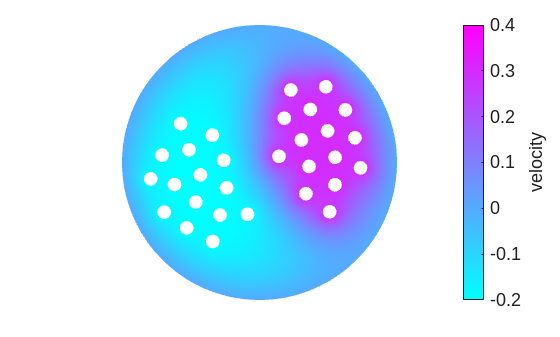

pdeplot(model.Mesh,'XYdata',full(u))


clim([-0.2 0.4])


axis equal
set(gca,'visible','off')
set(gca,'Ticklabelinterpreter','latex','FontSize',15)
c=colorbar;
c.Label.String='velocity';

%clear all
sum_kinesin=0;
sum_dynein=0;
counter=0;

N_points_to_budge=3;
x_before=x;
x=hold_drag(x,N_points_to_budge)
x-x_before

% N=3;
% p=1;
% x_test=[1/2 0;
%     -1/3 1/4;
%     -1/2 -1/6];
% 
% beta_1=norm(x_test(1,:))
% beta_2=norm(x_test(2,:))
% beta_3=norm(x_test(3,:))
% e_1=x_test(1,:)/beta_1;
% e_2=x_test(2,:)/beta_2;
% e_3=x_test(3,:)/beta_3;
% 
% Lagrangian(N,p,x_test,1,1,'closed')
% log(1-beta_1^2)-(1-beta_1^2)^2
% log(1-beta_2^2)-(1-beta_2^2)^2
% log(1-beta_3^2)-(1-beta_3^2)^2
% -log(norm(beta_1*e_1-beta_2*e_2)/norm(beta_1*beta_2*e_1-e_2))+...
%     -(1-beta_1^2)*(1-beta_2^2)
% -log(norm(beta_1*e_1-beta_3*e_3)/norm(beta_1*beta_3*e_1-e_3))+...
%     -(1-beta_1^2)*(1-beta_3^2)
% -log(norm(beta_2*e_2-beta_3*e_3)/norm(beta_2*beta_3*e_2-e_3))+...
%     -(1-beta_2^2)*(1-beta_3^2)
% 
% Lagrangian(N,p,x_test,1,1,'open')
% log(1-beta_1^2)
% log(1-beta_2^2)
% log(1-beta_3^2)
% -log(norm(beta_1*e_1-beta_2*e_2)/norm(beta_1*beta_2*e_1-e_2))
% -log(norm(beta_1*e_1-beta_3*e_3)/norm(beta_1*beta_3*e_1-e_3))
% -log(norm(beta_2*e_2-beta_3*e_3)/norm(beta_2*beta_3*e_2-e_3))

syms beta_1 beta_2 real

assume(beta_1>0); assumeAlso(beta_2>0); assumeAlso(beta_1<1); assumeAlso(beta_2<1);
f=log(1-beta_1^2)+log(1-beta_2^2)-(beta_1^2-beta_2^2)^2+2*log((beta_1+beta_2)/(1+beta_1*beta_2));
eq_1=lhs(simplify(diff(f,beta_1)==0))-rhs(simplify(diff(f,beta_1)==0))
eq_2=lhs(simplify(diff(f,beta_2)==0))-rhs(simplify(diff(f,beta_2)==0))
subs(expand(eq_1-eq_2),beta_1,beta_2)

% function y=Lagrangian(N,p,x) 
% tic
% % x is an Nx2 matrix
% A=zeros(N);
% for i=1:N
%     for j=1:N
%         A(i,j)=-log(norm(x(i,:)-x(j,:))/norm(norm(x(j,:))*x(i,:)-x(j,:)/norm(x(j,:))))-...
%             (1-norm(x(i,:))^2)*(1-norm(x(j,:))^2);
%     end
% end
% 
% for i=1:N
%     A(i,i)=log(1-norm(x(i,:))^2)-(1-norm(x(i,:))^2)^2;
% end 
% vec=[ones(p,1); -ones(N-p,1)];
% y=vec'*A*vec;
% toc
% end

function y=hold_drag(x,N_points)
y=x;
for count=1:N_points
p=drawpoint;
p_new=drawpoint;
y(vecnorm(x-p.Position,2,2)==min(vecnorm(x-p.Position,2,2)),:)=...
    p_new.Position;
end
end

function y=Lagrangian(N,p,x,xi,psi,state)

if strcmp(state,'closed')
A=-0.5*log((vecnorm(x,2,2).^2+(vecnorm(x,2,2).^2)'-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)')./...
(1-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)'+(vecnorm(x,2,2).*vecnorm(x,2,2)').^2))+...
-(1-vecnorm(x,2,2).^2)*(1-vecnorm(x,2,2).^2)';
A(1:N+1:N^2)=log(1-vecnorm(x,2,2).^2)-(1-vecnorm(x,2,2).^2).^2;
y=[xi*ones(1,p), -ones(1,N-p)]*A*[psi*ones(p,1); -ones(N-p,1)];
end

if strcmp(state,'open')
A=-0.5*log((vecnorm(x,2,2).^2+(vecnorm(x,2,2).^2)'-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)')./...
(1-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)'+(vecnorm(x,2,2).*vecnorm(x,2,2)').^2));
A(1:N+1:N^2)=log(1-vecnorm(x,2,2).^2);
y=[xi*ones(1,p), -ones(1,N-p)]*A*[psi*ones(p,1); -ones(N-p,1)];
end

if ~strcmp(state,'open') && ~strcmp(state,'closed')
    error('Specify the axon state as open or closed')
end

end



function pseudo_velocities=Velocities(N,p,x,xi,psi,state)

if strcmp(state,'closed')
A=-0.5*log((vecnorm(x,2,2).^2+(vecnorm(x,2,2).^2)'-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)')./...
(1-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)'+(vecnorm(x,2,2).*vecnorm(x,2,2)').^2))+...
-(1-vecnorm(x,2,2).^2)*(1-vecnorm(x,2,2).^2)';
A(1:N+1:N^2)=log(1-vecnorm(x,2,2).^2)-(1-vecnorm(x,2,2).^2).^2;
pseudo_velocities=diag([xi*ones(1,p),-ones(1,N-p)])*A*[psi*ones(p,1); -ones(N-p,1)];
end

if strcmp(state,'open')
A=-0.5*log((vecnorm(x,2,2).^2+(vecnorm(x,2,2).^2)'-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)')./...
(1-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)'+(vecnorm(x,2,2).*vecnorm(x,2,2)').^2));
A(1:N+1:N^2)=log(1-vecnorm(x,2,2).^2);
pseudo_velocities=diag([xi*ones(1,p),-ones(1,N-p)])*A*[psi*ones(p,1); -ones(N-p,1)];
end

if ~strcmp(state,'open') && ~strcmp(state,'closed')
    error('Specify the axon state as open or closed')
end

end


function y=Lagrangian_alpha(N,p,x,xi,psi,alpha)

A=-0.5*log((vecnorm(x,2,2).^2+(vecnorm(x,2,2).^2)'-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)')./...
(1-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)'+(vecnorm(x,2,2).*vecnorm(x,2,2)').^2))+...
-(1+alpha)^(-1)*(1-vecnorm(x,2,2).^2)*(1-vecnorm(x,2,2).^2)';
A(1:N+1:N^2)=log(1-vecnorm(x,2,2).^2)-(1+alpha)^(-1)*(1-vecnorm(x,2,2).^2).^2;
y=[xi*ones(1,p), -ones(1,N-p)]*A*[psi*ones(p,1); -ones(N-p,1)];

end




function y=Lagrangian_Gradient(N,p,x,xi,psi,delta,state)
y=zeros(N,2);
for i=1:N
    for j=1:2
        x_test_1=x;
        x_test_2=x;
        x_test_1(i,j)=x_test_1(i,j)+delta;
        x_test_2(i,j)=x_test_1(i,j)-delta;

y(i,j)=(Lagrangian(N,p,x_test_1,xi,psi,state)-Lagrangian(N,p,x_test_2,xi,psi,state))/(2*delta);
    end
end
y=y./vecnorm(y,2,2);
end

function y=Lagrangian_Gradient_alpha(N,p,x,xi,psi,delta,alpha)
y=zeros(N,2);
for i=1:N
    for j=1:2
        x_test_1=x;
        x_test_2=x;
        x_test_1(i,j)=x_test_1(i,j)+delta;
        x_test_2(i,j)=x_test_1(i,j)-delta;

y(i,j)=(Lagrangian_alpha(N,p,x_test_1,xi,psi,alpha)-Lagrangian_alpha(N,p,x_test_2,xi,psi,alpha))/(2*delta);
    end
end
end

% function y=contain(x,x_1)
% ind=find(vecnorm(x_1,2,2)>=1);
% y=x_1;
% y(ind,:)=x(ind,:);
% end

function y=contain_1(x,delta)
ind=find(vecnorm(x,2,2)>=1-delta);
y=x;
y(ind,:)=(1-delta)*x(ind,:)./vecnorm(x(ind,:),2,2);
end

function y=segregate(x,x_old,x_start,fun)
% for each x(i,:), fun_vector(i) is a function that must stay positive at
% all times
y=(fun(x,x_start)>=0).*x+(fun(x,x_start)<0).*x_old;
end

function y=repel(x,min_distance)
N=size(x,1);
dist=sqrt(vecnorm(x,2,2).^2+(vecnorm(x,2,2).^2)'-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)');
dist(1:N+1:N^2)=1;
n_count=0;

while any(dist<min_distance,'all') && n_count<1000

for i=1:N
    for j=i+1:N
        if dist(i,j)<min_distance
            midpoint=(x(i,:)+x(j,:))/2;
            normal=(x(i,:)-x(j,:))/norm(x(i,:)-x(j,:));
            x(i,:)=midpoint+min_distance*normal/2;
            x(j,:)=midpoint-min_distance*normal/2;
        end
    end
end
dist=sqrt(vecnorm(x,2,2).^2+(vecnorm(x,2,2).^2)'-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)');
dist(1:N+1:N^2)=1;
n_count=n_count+1;
end

% while any(dist<0.05,'all') && n_count<1000
%     x=x+0.05*randn(N,2);
%     dist=sqrt(vecnorm(x,2,2).^2+(vecnorm(x,2,2).^2)'-2*x(:,1)*x(:,1)'-2*x(:,2)*x(:,2)');
% dist(1:N+1:N^2)=1;
% n_count=n_count+1;
% end
y=x;
end


function [V, C] = BoundVoronoin_UnitCircle(V, C, varargin)
global x_VoronoiGlobal y_VoronoiGlobal
if isempty(varargin) ||  (varargin{1}==0)
    toggleplot = false;
else
    toggleplot = true;
end
% An arbitrarily selected small number for distance comparison
Epsilon = 1e-14;
x = x_VoronoiGlobal;
y = y_VoronoiGlobal;
%% Identify points with unbounded cell
LenC = length(C); % equals to M
ptUnbound = [];
for index = 1 : LenC
    if ismember(1,C{index})  % Unbounded cell
        ptUnbound = [ptUnbound;index]; %#ok<AGROW>
    end
end
% List the unbounded cells in counter-clockwise direction
UnboundCentre = mean([x(ptUnbound),y(ptUnbound)],1);
Angle = atan2(y(ptUnbound)-UnboundCentre(2),x(ptUnbound)-UnboundCentre(1));
[Angle,ptptUnbound] = sort(Angle); %#ok<ASGLU>
ptUnbound = ptUnbound(ptptUnbound);
Orphan_x = x(ptUnbound);
Orphan_y = y(ptUnbound);
if toggleplot
    [vx,vy] = voronoi(x,y);
    figure(1)
    plot(cos(linspace(0,2*pi,100)),sin(linspace(0,2*pi,100)),'k-')
    hold on
    plot(vx,vy,'b:',V(2:end,1),V(2:end,2),'gx')
    plot(x,y,'c.')
    plot(Orphan_x,Orphan_y,'k.')
    hold off
    axis square; axis([-2 2 -2 2])
    set(gcf, 'Color', [1 1 1])
    set(gca,'FontSize', 14)
end
%% Find suitable replacement for infinity points
% Pointer to the next(circular) unbounded cell
ptNext = [2:length(ptUnbound),1];
for index = 1 : length(ptUnbound)
    
    ptV = C{ptUnbound(index)};
    
    % =====================================================================
    if toggleplot
        % Display voronoi diagram
        figure(2)
        plot(Orphan_x,Orphan_y,'k.')
        hold on
        plot(x(ptUnbound(index)),y(ptUnbound(index)),'r.')
        plot(cos(linspace(0,2*pi,100)),sin(linspace(0,2*pi,100)),'k-')
        plot(vx,vy,'b:')
        for jndex = 1 : length(ptV)
            if ptV(jndex) ~= 1
                plot(V(ptV(jndex),1),V(ptV(jndex),2),'gx');
            end
        end
        axis square; axis([-2 2 -2 2])
        set(gcf, 'Color', [1 1 1])
        set(gca,'FontSize', 14)
    end
    % =====================================================================
    
    P1x         = Orphan_x(index);
    P1y         = Orphan_y(index);
    P2x_Next    = Orphan_x(ptNext(index));
    P2y_Next    = Orphan_y(ptNext(index));
    
    ptVFinite   = setdiff(ptV,[1]);
    
    % Identify voronoi vertex that is closest to the proposed perpendicular bisector
    Dist            = abs(V(ptVFinite,1)*(P1x-P2x_Next) + V(ptVFinite,2)*(P1y-P2y_Next) -(P1y^2-P2y_Next^2+P1x^2-P2x_Next^2)/2);
    [MinDist,jndex] = min(Dist); %#ok<ASGLU>
    
    NormVoronoiPoint = realsqrt(sum(V(ptVFinite(jndex),:).^2));
    
    % Identifies the points that uses ptVFinite(jndex) as voronoi vertice
    ptP = [];    bContinue = true;   Counter=0;      PCounter=0;
    while bContinue
        Counter = Counter + 1;
        if ismember(ptVFinite(jndex),C{Counter})
            PCounter = PCounter + 1;
            ptP(PCounter) = Counter;
            if PCounter>=3
                bContinue = false;
            end
        end
        if Counter >= LenC
            bContinue = false;
        end
    end
    
    % Find the bisector and append the new point to appropriate entries in C
    for Counter1 = 1 : PCounter-1
        for Counter2 = Counter1 + 1 : PCounter
            
            ptLocalVSet = setdiff(union(C{ptP(Counter1)},C{ptP(Counter2)}),[1,ptVFinite(jndex)]);
            % Equation of bisector (y-y0)(dy)+(x-x0)(dx)=0
            MidPoint    = 0.5*[x(ptP(Counter1))+x(ptP(Counter2)),y(ptP(Counter1))+y(ptP(Counter2))];
            dx          = x(ptP(Counter1))-x(ptP(Counter2));
            dy          = y(ptP(Counter1))-y(ptP(Counter2));
            VecLen      = realsqrt(dx^2+dy^2);
            dx          = dx/VecLen;
            dy          = dy/VecLen;
            DistBisect  = abs( (V(ptLocalVSet,1)-MidPoint(1))*dx + (V(ptLocalVSet,2)-MidPoint(2))*dy );
            bNoHit      = DistBisect > Epsilon;
            if all(bNoHit)
                
                % Can't find a finite voronoi vertice to complement ptVFinite(jndex)
                % Create a new point outside the unit circle
                if NormVoronoiPoint > 1
                    Lambda = 2*NormVoronoiPoint;
                else
                    Lambda = NormVoronoiPoint;
                end
                
                P_ex1 = V(ptVFinite(jndex),:) + Lambda*[dy,-dx];
                P_ex2 = V(ptVFinite(jndex),:) + Lambda*[-dy,dx];
                
                Dist1 = sort(realsqrt((P_ex1(1)-x(ptP)).^2+(P_ex1(2)-y(ptP)).^2));
                Dist2 = sort(realsqrt((P_ex2(1)-x(ptP)).^2+(P_ex2(2)-y(ptP)).^2));
                
                Direction = [];
                if (Dist1(3)-Dist1(2) > 0) && (abs(Dist1(2)-Dist1(1))<Epsilon)
                    Direction = 1;
                elseif (Dist2(3)-Dist2(2) > 0) && (abs(Dist2(2)-Dist2(1))<Epsilon)
                    Direction = 2;
                end
                if ~isempty(Direction)
                    bContinue = true;
                    while bContinue
                        if Direction == 1
                            P_ex = V(ptVFinite(jndex),:) + Lambda*[dy,-dx];
                        elseif Direction == 2
                            P_ex = V(ptVFinite(jndex),:) + Lambda*[-dy,dx];
                        end
                        if realsqrt(sum((P_ex.^2),2))>1
                            bContinue = false;
                            V = [V;P_ex]; %#ok<AGROW>
                            C{ptP(Counter1)} = [C{ptP(Counter1)},size(V,1)];
                            C{ptP(Counter2)} = [C{ptP(Counter2)},size(V,1)];
                            if toggleplot
                                plot(V(end,1),V(end,2),'md')
                            end
                        else
                            Lambda = 2*Lambda;
                        end
                    end
                end
            end
            
        end % End of Counter 2
    end % End of Counter 1
    
    if toggleplot
        hold off
    end
end
%% Sort angle, all vertices in anti-clockwise direction
for index = 1 : LenC
    
    ptVFinite = setdiff(C{index},[1]);
    
    if toggleplot
        figure(3)
        plot(Orphan_x,Orphan_y,'.',x(index),y(index),'r*',cos(linspace(0,2*pi,100)),sin(linspace(0,2*pi,100)),'k-')
        hold on
        plot(vx,vy,'b:')
        plot(V(ptVFinite,1),V(ptVFinite,2),'gx');
        axis([min(V(:,1)) max(V(:,1)) min(V(:,2)) max(V(:,2))])
        axis square; axis([-2 2 -2 2])
        set(gcf, 'Color', [1 1 1])
        set(gca,'FontSize', 14)
    end
    
    Centre = mean(V(ptVFinite,:),1);
    Angle = atan2(V(ptVFinite,2)-Centre(2),V(ptVFinite,1)-Centre(1));
    [Angle,jndex] = sort(Angle); %#ok<ASGLU>
    C{index} = ptVFinite(jndex); %Sorted voronoi vertices
    
    if toggleplot
        hold off
    end
end
end

function [xc, yc] = BoundaryIntersect_UnitCircle(P1, P2, Mode)
M = size(P1,1);
x1 = P1(:,1);
y1 = P1(:,2);
x2 = P2(:,1);
y2 = P2(:,2);
dx = x1 - x2;
dy = y1 - y2;
bNonsingular = (dx~=0);
bSingular    = ~bNonsingular;
        
switch Mode
    
    case 1
        % One point outside of unit circle while the other inside
        xc = zeros(M,1);
        yc = zeros(M,1);
        
        % Non-singular case
        if any(bNonsingular)    % Regular equation of line
            m = zeros(length(dx),1);
            c = zeros(length(dx),1);
        
            m(bNonsingular) = dy(bNonsingular)./dx(bNonsingular);
            c(bNonsingular) = P1(bNonsingular,2) - m(bNonsingular).*P1(bNonsingular,1);
            
            % Calculate circle intersect
            mc = m(bNonsingular).*c(bNonsingular);
            m2 = m(bNonsingular).^2;
            c2 = c(bNonsingular).^2;
            % Determinant is always positive due to the point configuration
            SqrtDeterminant = realsqrt(mc.^2 - (m2+1).*(c2-1)); 
            
            xBoundary1 = (-mc + SqrtDeterminant)./(m2+1);
            xBoundary2 = (-mc - SqrtDeterminant)./(m2+1);
            yBoundary1 = m(bNonsingular).*xBoundary1 + c(bNonsingular);
            yBoundary2 = m(bNonsingular).*xBoundary2 + c(bNonsingular);
            intersect1(bNonsingular,:) = [xBoundary1, yBoundary1];
            intersect2(bNonsingular,:) = [xBoundary2, yBoundary2];
        end
        
        % Singular case
        if any(bSingular)   % vertical line
            % Calculate circle intersect
            xBoundary = x1(bSingular);
            yBoundary = sqrt(1 - xBoundary.^2);
            intersect1(bSingular,:) = [xBoundary, yBoundary];
            intersect2(bSingular,:) = [xBoundary,-yBoundary];
        end
        
        % The dot product of (p1-intersect).(p2-intersect) is negative if the intersection point
        % lie between two points, as the two vectors take on different direction
        % Due to the point configuration, only one "intersect" test is
        % needed (the other one is logial compliment)
        v1 = sum((P1-intersect1).*(P2-intersect1),2);
%         v2 = sum((P1-intersect2).*(P2-intersect2),2);
        
        v1neg = v1<0;
        v2neg = ~v1neg;
        
        xc(v1neg) = intersect1(v1neg,1);
        xc(v2neg) = intersect2(v2neg,1);
        yc(v1neg) = intersect1(v1neg,2);
        yc(v2neg) = intersect2(v2neg,2);
        
        
    case 2
        % Both points are outside of unit circle
        xc = nan(size(P1,1),2);
        yc = nan(size(P1,1),2);
        
        if any(bNonsingular)    % Regular equation of line
                   
            m = dy(bNonsingular)./dx(bNonsingular);
            c = y1(bNonsingular) - m.*x1(bNonsingular);
            
            % Calculate circle intersect
            mc = m.*c;
            m2 = m.^2;
            c2 = c.^2;
            Determinant = mc.^2 - (m2+1).*(c2-1);
            SqrtDeterminant = sqrt(Determinant);
            
            xBoundary(:,1) = (-mc + SqrtDeterminant)./(m2+1);
            xBoundary(:,2) = (-mc - SqrtDeterminant)./(m2+1);
            yBoundary(:,1) = m.*xBoundary(:,1) + c;
            yBoundary(:,2) = m.*xBoundary(:,2) + c;
            % Remove complex solutions
            xBoundary(Determinant<0,1:2) = nan;
            yBoundary(Determinant<0,1:2) = nan;
            
            % Ensures that [xc,yc] is between the two voronoi vertices. 
            % Perform dot product on one point is sufficient
            v = sum((P1(bNonsingular,:)-[xBoundary(:,1),yBoundary(:,1)])...
                    .* (P2(bNonsingular,:)-[xBoundary(:,1),yBoundary(:,1)]),2);
            
            xBoundary(v>0,1:2) = nan;
            yBoundary(v>0,1:2) = nan;
            
            xc(bNonsingular,:) = xBoundary;
            yc(bNonsingular,:) = yBoundary;
        end
        
        if any(bSingular)   % vertical line
            xBoundary = P1(bSingular,1);
            xBoundary(abs(xBoundary)>1)= nan;
            xc(bSingular,:) = repmat(xBoundary,1,2);
            yc(bSingular,1) = realsqrt(1 - xBoundary.^2);
            yc(bSingular,2) = -yc(bSingular,1);
        end
        
end
end

function CellArea = CalcArea_UnitCircle(VSet, V1, V2, ptS)
global x_VoronoiGlobal y_VoronoiGlobal
x = x_VoronoiGlobal;
y = y_VoronoiGlobal;
S               = [x(ptS),y(ptS)];
xOther          = x;
xOther(ptS)     = [];
yOther          = y;
yOther(ptS)     = [];
VBoundary       = [V1;V2];
VAll            = [VSet;VBoundary];
Centre          = mean(VAll,1);
% SAngle          = atan2(S(2)-Centre(2),S(1)-Centre(1));
% Angle           = atan2([VBoundary(:,2)]-Centre(2),[VBoundary(:,1)-Centre(1)]);
Angle           = atan2([VBoundary(:,2)],[VBoundary(:,1)]);
[Angle,index]   = sort(Angle);
VBoundary       = VBoundary(index,:);
% Starting point is characterised by ascribed angle greater than pi
AngleNext           = [Angle(2:end);Angle(1)];
DAngle              = AngleNext-Angle;
bCrossOver          = DAngle < 0;
DAngle(bCrossOver)  = DAngle(bCrossOver) + 2*pi;
RefAngle = Angle + 0.5*DAngle;
RefPoint = [cos(RefAngle),sin(RefAngle)];
% [MaxDAngle,index]   = max(DAngle);
% VBoundary           = circshift(VBoundary,[-index+1,0]);
% Angle               = circshift(Angle,[-index+1,0]);
% DAngle              = circshift(DAngle,[-index+1,0]);
ptNext      = [2:size(VBoundary,1),1];
SegAreaV    = 0;
for index = 1 : size(VBoundary,1)
    % Determine if there is a point inside the segment
    dx = VBoundary(index,1)-VBoundary(ptNext(index),1);
    dy = VBoundary(index,2)-VBoundary(ptNext(index),2);
    Side    = sign((xOther-VBoundary(index,1))*dy - (yOther-VBoundary(index,2))*dx);
    RefSide = sign((RefPoint(index,1)-VBoundary(index,1))*dy - (RefPoint(index,2)-VBoundary(index,2))*dx);
    if ~any(Side==RefSide)
        segAngV = atan2(VBoundary(ptNext(index),2),VBoundary(ptNext(index),1))-atan2(VBoundary(index,2),VBoundary(index,1));
        if segAngV < 0
            segAngV = segAngV + 2*pi;
        end
        SegAreaV  = SegAreaV  + 0.5*(segAngV-sin(segAngV));
    end
end
if size(VAll,1)>2
    vec             = VAll - repmat(Centre, size(VAll,1),1);
    Angle           = atan2(vec(:,2),vec(:,1));
    [sorted,index]  = sort(Angle); %#ok<ASGLU>
    VAll            = VAll(index,:);
    PolygonArea     = polyarea(VAll(:,1), VAll(:,2));
else
    PolygonArea     = 0;
end
CellArea = PolygonArea + SegAreaV;
end

function CellArea=CircleBV(x,y,toggleplot)
% CIRCLEBV   Circle Bounded Voronoi Diagram
% This function compute the individual Voronoi cell area of point sets
% bounded in a unit circle
% Written by / send comments or suggestions to :
% Meng Sang, Ong (ongdotmengdotsangatengdotmonashdotedudotmy) & Ye Chow, Kuang (kuangdotyedotchowatmonashdotedu)
% Photonic, Semiconductor & Communication Research Group
% School of Engineering
% Monash University Sunway campus
% October 2010
% Inputs:
%   x          : M x 1 array of x-coordinates
%   y          : M x 1 array of y-coordinates
%   toggleplot : 1 to turn on figures (may take longer time for large samples) 
%                0 to turn off figures;
% Outputs:
%   CellArea   : M x 1 array of Voronoi cell area bounded in a unit circle
if any(size(x) ~= size(y))
    error('x,y dimensions are not consistent')
end
x=x(:); y=y(:); 
clear global x_VoronoiGlobal y_VoronoiGlobal
global x_VoronoiGlobal y_VoronoiGlobal
if toggleplot
    plottools('on')
    propertyeditor('off')
    figure(1);figure(2);figure(3);figure(4);
    set([1:4],'WindowStyle','docked');
end
x_VoronoiGlobal = x; %#ok<NASGU>
y_VoronoiGlobal = y; %#ok<NASGU>
% Voronoi tesselation using voronoin()
[V, C] = voronoin([x,y]);
[vx,vy] = voronoi(x,y);
% Force all voronoi vertices to be finite
[V,C] = BoundVoronoin_UnitCircle(V, C, toggleplot);
% ---------------------------------------------------------------------
% Find boundary intersection points and each voronoi cell areas
NormV = realsqrt(sum(V.^2,2));
LenC  = length(C);
CellArea = zeros(LenC,1);
for index = 1 : LenC
    ptV = C{index};
    VSet = V(ptV,:);
    NormVSet = NormV(ptV);
    
    % =================================================================
    if toggleplot
        figure(4);
        plot(cos(linspace(0,2*pi,100)),sin(linspace(0,2*pi,100)),'k-'); hold on
        plot(x,y,'.')
        plot(x(index),y(index),'r*')
        plot(vx,vy,'b:')
        for jndex = 1 : length(ptV)
            if ptV(jndex) ~= 1
                plot(V(ptV(jndex),1),V(ptV(jndex),2),'gx');
            end
        end
        axis([-2 2 -2 2]);
        axis square;
        set(gcf, 'Color', [1 1 1])
        set(gca,'FontSize', 14)
    end
    % =================================================================
    
    % Identify the vertice furthest from the origin to be the first scanning vertice
    if max(NormVSet) < 1
        % All points inside unit curcle, calculate area
        CellArea(index) = polyarea(V(ptV,1),V(ptV,2));
    else
        % Find points outside unit circle
        bOutside = NormVSet>1;
        bTestStartPoint = bOutside;
        bTestStartPoint = or(bTestStartPoint,circshift(bTestStartPoint,-1));
        ptComplimentaryPoint = mod(find(bTestStartPoint),length(VSet))+1;
        % Find intersection points (if exist)
        TestPoint1 = VSet(bTestStartPoint,:);
        TestPoint2 = VSet(ptComplimentaryPoint,:);
        if size(VSet,1) == 2
            TestPoint1(2,:) = [];
            TestPoint2(2,:) = [];
        end
        
        % =============================================================
        if toggleplot
            plot([TestPoint1(:,1),TestPoint2(:,1)]',[TestPoint1(:,2),TestPoint2(:,2)]','c:')
        end
        % =============================================================
        
        Norm1 = NormVSet(bTestStartPoint);
        Norm2 = NormVSet(ptComplimentaryPoint);
        if size(VSet,1) == 2
            Norm1(2,:) = [];
            Norm2(2,:) = [];
        end
        
        bOneInOneOut= xor(Norm1>1,Norm2>1);
        if any(bOneInOneOut)
            [xc1, yc1]  = BoundaryIntersect_UnitCircle(TestPoint1(bOneInOneOut,:),TestPoint2(bOneInOneOut,:),1);
        else
            xc1 = [];
            yc1 = [];
        end
        bTwoOut     = and(Norm1>1,Norm2>1);
        if any(bTwoOut)
            [xc2, yc2]  = BoundaryIntersect_UnitCircle(TestPoint1(bTwoOut,:),TestPoint2(bTwoOut,:),2);
            xc2 = reshape(xc2,numel(xc2),1);
            yc2 = reshape(yc2,numel(yc2),1);
            xc2(isnan(xc2)) = [];
            yc2(isnan(yc2)) = [];
        else
            xc2 = [];
            yc2 = [];
        end
        
        % =============================================================
        if toggleplot
            if ~isempty(xc1)
                plot(xc1,yc1,'mx');
            end
            if ~isempty(xc2)
                plot(xc2,yc2,'mx');
            end
        end
        % =============================================================
        
        % Calculate call area
        CellArea(index) = CalcArea_UnitCircle(VSet(NormVSet<=1,:), [xc1,yc1], [xc2,yc2], index);
    end
    
    % =================================================================
    if toggleplot
        hold off
        % pause(0.8)
    end
    % =================================================================
    
end
TotalArea = sum(CellArea);
Err = TotalArea-pi;
%fprintf('Mean absolute Error = %.3e\n',mean(abs(Err)))
%fprintf('Largest absolute Error = %.3e\n',max(abs(Err)))
clear global x_VoronoiGlobal y_VoronoiGlobal
end



